# **EFTERÅR 2015 RE-EKSAMEN**

***MADS STEINER KRISTENSEN***

***AARHUS UNIVERSITY - AARHUS SCHOOL OF ENGINEERING***

clc
clear

addpath('[0] Library');
Color = load("colors.mat");
smp = load("library.mat");

# **1 STOKASTISKE VARIABLE**

**En kontinuært stokastisk variabel har følgende fordelingsfunktion (cdf): **


$$\left.F_X \left(x\right)=\left\lbrace \begin{array}{cc}
k\cdot e^x  & -\infty <x\le 1\\
1 & 1<x
\end{array}\right.\right\rbrace$$


## 1.1 TÆTHEDSFUNKTION

**Vis at tæthedsfunktionen (pdf) er givet ved**


$$\left.f_X \left(x\right)=\left\lbrace \begin{array}{cc}
k\cdot e^x  & -\infty <x\le 1\\
0 & 1<x
\end{array}\right.\right\rbrace$$


Tæthedsfunktionen findes som $f_x \left(x\right)=\frac{{\mathrm{dF}}_X \left(x\right)}{\mathrm{dx}}$, hvorved

syms x k
f = k * exp(x);
diff(f, x)

$$ans = k\,{\mathrm{e}}^{x}$$

f = sym('1');
diff(f)

$$ans = 0$$

Hvilket dermed givet, at 


$$\left.f_X \left(x\right)=\left\lbrace \begin{array}{cc}
k\cdot e^x  & -\infty <x\le 1\\
0 & 1<x
\end{array}\right.\right\rbrace$$


## 1.2 GYLDIG TÆTHEDSFUNKTION

**For hvilken værdi af k er **$f_x \left(x\right)$**en gyldig tæthedsfunktion?**

En PDF er gyldig når 


$$\;\int_{-\infty }^{\infty } f_x \left(x\right)\mathrm{dx}=1$$


og alle værdier af PDF'en er større eller lig med 0. Det vil sige, at 


$$\int_{-\infty }^1 k\cdot e^x \mathrm{dx}+\int_1^{\infty } 0\;\mathrm{dx}=1$$



$$k{\left\lbrack e^x \right\rbrack }_{-\infty }^1 =1$$



$$\underset{t\to \infty }{\mathrm{lim}} k\left(e^1 -e^{-t} \right)=1$$



$$k\cdot e=1\Rightarrow k=\frac{1}{e}$$


## 1.3 SANDSYNLIGHEDER

k = 1 / exp(1);

probability = k * exp(0.4); 

disp("Pr(x < 0.4) = " + probability);

Pr(x < 0.4) = 0.54881


probability = probability - (k * exp(0.1));

disp("Pr(0.1 <= x < 0.4) = " + probability);

Pr(0.1 <= x < 0.4) = 0.14224


## 1.4 FORVENTNINGSVÆRDI

Middelværdien / Forventningsværdien bestemmes som følgende,


$$E\left\lbrack X\right\rbrack =\overline{X} =\mu_x =\int_{-\infty }^{\infty } x\cdot f_x \left(x\right)\mathrm{dx}$$



$$E\left\lbrack X\right\rbrack =\int_{-\infty }^1 x\cdot f_x \left(x\right)\mathrm{dx}=\int_{-\infty }^1 x\cdot \frac{1}{e}\cdot e^x \mathrm{dx}$$


f = @(a) a.*1/exp(1).*exp(a);

value.expectation = round(integral(f, -inf, 1), 10);

disp("Forventningsværdien er bestemt til at være: " + value.expectation);

Forventningsværdien er bestemt til at være: 0



$$\mathrm{Var}\left(x\right)=\int_{-\infty }^{\infty } \left(x-\overline{x} \right)\cdot f_X \left(x\right)\mathrm{dx}=E\left\lbrack X^2 \right\rbrack -E{\left\lbrack X\right\rbrack }^2$$


f = @(a) (a.^2).*1/exp(1).*exp(a);

value.expectationsquared = round(integral(f, -inf, 1), 10);

disp("Variansen er bestemt til at være: " + (value.expectationsquared - value.expectation^2));

Variansen er bestemt til at være: 1


# **2 STOKASTISKE PROCESSER**

**En diskret stokastisk process er givet ved**


$$X\left(n\right)=w\left(n\right)+4$$


**Hvor hver sample n af w er i.i.d Gaussisk fordelte stokastiske variable w(n) ~ N(0,1).**

## **2.1 SKITSERING AF REALISATION**

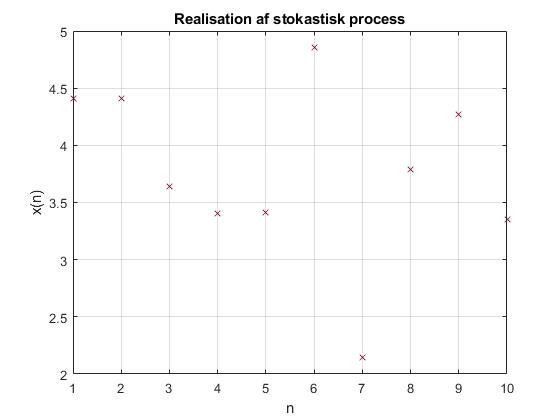

mu = 0;
sigma = 1;

realisation = (sigma * randn(1, 10) + mu) + 4;

figure(1)
plot(1:length(realisation), realisation, 'x', 'Color', Color.DeepCleret);
title('Realisation af stokastisk process');
xlabel('n')
ylabel('x(n)')
grid on

## 2.2 MIDDELVÆRDI OG VARIANS


$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack w\left(n\right)+4\right\rbrack$$



$$E\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack w\left(n\right)\right\rbrack +E\left\lbrack 4\right\rbrack$$


Ensemble.Mean = mu + 4;

disp("Ensemble middelværdien er: " + Ensemble.Mean);

Ensemble middelværdien er: 4



$$\mathrm{var}\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack {X\left(n\right)}^2 \right\rbrack -E{\left\lbrack X\left(n\right)\right\rbrack }^2$$



$$\mathrm{var}\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack {w\left(n\right)}^2 \right\rbrack +E\left\lbrack 4^2 \right\rbrack -4^2$$



$$\mathrm{var}\left\lbrack X\left(n\right)\right\rbrack =E\left\lbrack {w\left(n\right)}^2 \right\rbrack =\mathrm{var}\left(w\left(n\right)\right)=1$$


Ensemble.Variance = 1;

disp("Ensemble variansen er : "+ Ensemble.Variance);

Ensemble variansen er : 1


## 2.3 PROCESSEN

Processen er wide state stationary da middelværdien og varians ikke er tidsafhængige. Processen er ergodisk, da middelværdi og varianskan bestemmes ud fra en realisation.

# **3 SANDSYNLIGHED**

**Du spiller kort i et kasino. Der er et sæt af 52 kort i et spil, du trækker syv kort.**

## **3.1 HÆNDELSE HJERTE KONGE**

**EVENT A: HJERTER KONGE**

**EVENT B: SPAR ES**

Sandsynligheden for at trækker hjerte konge blandt de syv kort er som følgende. Der vil være syv muligheder blandt de allerede trukket kort for at finde en hjerter konge.

Cards = 52;
Drawings = 7;

A = Drawings / Cards;

disp("Sandsynligheden for at trække en hjerter konge blandt de syv kort er: " + A);

Sandsynligheden for at trække en hjerter konge blandt de syv kort er: 0.13462


## 3.2 HÆNDELSE SPAR ES OG HJERTET KONGE


$$P\left(B\right)=P\left(A\right)=0\ldotp 13462$$



$$P\left(A\cap B\right)=P\left(A|B\right)\cdot P\left(B\right)$$


B = Drawings / Cards;

AGivenB = (Drawings - 1) / (Cards - 1);

AAndB = AGivenB * B;

disp("Sandsynligheden for at hjerter konge og spar es er blandt de syv trukne kort er: " + AAndB);

Sandsynligheden for at hjerter konge og spar es er blandt de syv trukne kort er: 0.015837


## 3.3 UAFHÆNGIGHED

For at tjekke om der er uafhængig gælder følgende udtryk for uafhængighed


$$P\left(A\right)\cdot P\left(B\right)=P\left(A\cap B\right)$$


if A * B == AAndB
    disp("A og B er uafhængige");
else
    disp("A og B er ikke uafhængige");
end

A og B er ikke uafhængige


## 3.4 KOMBINATIONER

Det antages at eksperimentet ikke er i orden og er uden tilbagelægning, derved gælder, at (k objects out of collection of n objects)


$$\left(\frac{n}{k}\right)=\frac{n!}{k!\left(n-k\right)!}$$


n = 52;
k = 7;

Combinations = factorial(n) / (factorial(k) * factorial(n-k));

disp("Antallet af kombinationer med 7 kort er: " + Combinations);

Antallet af kombinationer med 7 kort er: 133784560


# **4 STATISTIK**

**Den gennemsnitlige alder for 1. gangs viede mænd i Danmark er angivet ved følgende tabel**


$$\left\lbrack \begin{array}{cccccccccc}
\mathrm{Alder} & 25\ldotp 2 & 26\ldotp 5 & 27\ldotp 9 & 29\ldotp 2 & 30\ldotp 2 & 31\ldotp 7 & 32\ldotp 8 & 34\ldotp 0 & 34\ldotp 3\\
\mathrm{År} & 1971 & 1976 & 1981 & 1986 & 1991 & 1996 & 2001 & 2006 & 2011
\end{array}\right\rbrack$$


## **4.1 PLOT DATA**

Til denne opgave anvendes lineær tilnærmelse, hvor


$$\hat{x} =\beta \cdot t+\alpha$$


Dertil anvendes, at 


$$\beta^ˆ =\frac{\sum_{i=1}^n \left(x-\overline{x} \right)\cdot \left(y-\overline{y} \right)}{\sum_{i=1}^n {\left(x-\overline{x} \right)}^2 }$$



$$\alpha^ˆ =\overline{y} -\beta^ˆ \cdot \overline{x}$$


Samt at der for middelværdien gælder, at


$$\overline{x} =\frac{1}{n}\cdot \sum_{i=1}^n x_i$$


Year = [1971, 1976, 1981, 1986, 1991, 1996, 2001, 2006, 2011];
Age = [25.2, 26.5, 27.9, 29.2, 30.2, 31.7, 32.8, 34.0, 34.3];

AgeMean = mean(Age);
YearMean = mean(Year);

beta = sum((Age - AgeMean) .* (Year - YearMean)) / sum((Year - YearMean).^2);
alpha = AgeMean - beta * YearMean;
Fitting = beta * Year + alpha;

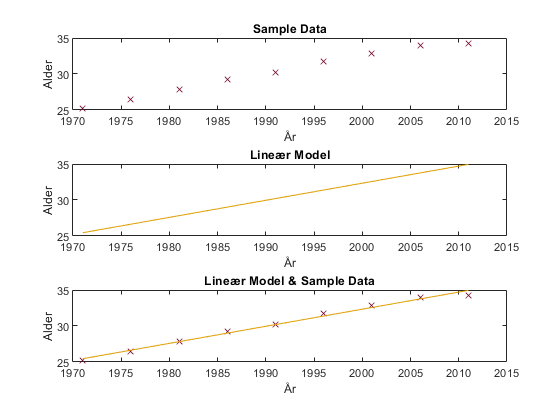

figure(2)
subplot(3,1,1,gca)
plot(Year, Age, 'x', 'Color', Color.DeepCleret);
title('Sample Data');
xlabel('År');
ylabel('Alder');

subplot(3,1,2)
plot(Year, Fitting, 'Color', Color.BurntYellow);
title('Lineær Model');
xlabel('År');
ylabel('Alder');

subplot(3,1,3)
plot(Year, Age, 'x', 'Color', Color.DeepCleret);
hold on
plot(Year, Fitting, 'Color', Color.BurntYellow);
title('Lineær Model & Sample Data');
xlabel('År');
ylabel('Alder');
hold off

## 4.2 RESIDUALTEGNING

Til at tegne residualer og beregne disse anvendes følgende udtryk.


$$\epsilon_{i\;} =y_i -\left(\alpha +\beta \cdot x_i \right)$$


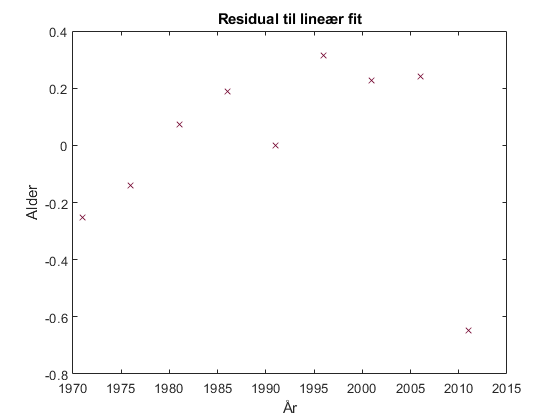

Residuals = Age - (alpha + beta * Year);

figure(6)
plot(Year, Residuals, 'kx', 'Color', Color.DeepCleret);
title('Residual til lineær fit');
xlabel('År');
ylabel('Alder');

## 4.3 STATISTISK TEST

Da variansen er ukendt og data er gaussiske og ikke parret, benyttes en t-test for sammenligning af middelværdier.